%% =============================================================
%  CP-PLL Phase Noise Analysis — v2 (Step 1 fixes)
%  
%  Changes from v1:
%  [S1] Reference noise slope fixed: -3 → -30 dB/decade
%  [S3] All manual scaling knobs removed. Every noise source from physics.
%  [I1] Frequency grid: linear → logarithmic
%  [I4] CP noise from shot noise: S_i = 4*q*Icp
%
%  Figures (3 total, streamlined):
%    Fig 1 — Noise transfer functions (the shaping mechanism)
%    Fig 2 — Total output PN PSD + improvement vs free VCO
%    Fig 3 — Per-source noise shaping (source vs output, 4 panels)
% =============================================================
clear; clc; close all;

%% === 1. PLL Parameters ===================================================
fref = 10e6;                  % reference clock frequency, Hz
N    = 10;                    % division ratio
Icp  = 45e-6;                 % charge pump current, A
Kpd  = Icp/(2*pi);            % PFD/CP gain, A/rad
Kvco = 2*pi*250e6;            % VCO gain, rad/(s·V)
R1   = 4.92e3;                % loop filter resistor, Ohm
C1   = 1.508e-10;             % capacitor C1, F
C2   = 1.167e-11;             % capacitor C2, F
fout = fref * N;              % output frequency, Hz

fprintf('=== PLL Parameters ===\n');

=== PLL Parameters ===


fprintf('fref = %.2f MHz,  N = %d,  fout = %.2f MHz\n', fref/1e6, N, fout/1e6);

fref = 10.00 MHz,  N = 10,  fout = 100.00 MHz


fprintf('Icp = %.1f uA,  Kpd = %.3f uA/rad\n', Icp*1e6, Kpd*1e6);

Icp = 45.0 uA,  Kpd = 7.162 uA/rad


fprintf('Kvco = %.2f MHz/V\n', Kvco/(2*pi*1e6));

Kvco = 250.00 MHz/V


fprintf('R1 = %.2f kOhm,  C1 = %.1f pF,  C2 = %.2f pF\n', R1/1e3, C1*1e12, C2*1e12);

R1 = 4.92 kOhm,  C1 = 150.8 pF,  C2 = 11.67 pF



%% === 2. Frequency Grid (LOGARITHMIC) =====================================
f = logspace(log10(1e3), log10(300e6), 2000);
w = 2*pi*f;

%% === 3. Physically-Derived Noise Models ===================================
q  = 1.602e-19;
kB = 1.38e-23;
T  = 300;

% ----- 3.1  Reference oscillator phase noise -----
% Anchor: -150 dBc/Hz at 1 kHz (typical 10 MHz TCXO)
% Slope:  -30 dB/dec (1/f^3 flicker region)
% Floor:  -170 dBc/Hz (buffer thermal limit)
PN_ref_anchor = -150;
f_ref_anchor  = 1e3;
ref_slope     = -30;
PN_ref_floor  = -170;

PN_ref = max(PN_ref_anchor + ref_slope * log10(f / f_ref_anchor), ...
             PN_ref_floor);

% ----- 3.2  VCO intrinsic phase noise (Leeson model) -----
% Three-region piecewise: 1/f^3 (close-in) + 1/f^2 (mid) + floor (far)
% Anchor: -90 dBc/Hz at 100 kHz (in 1/f^2 region)
% 1/f corner: below this frequency, slope steepens to -30 dB/dec
PN_vco_anchor = -90;           % dBc/Hz at f_vco_anchor
f_vco_anchor  = 100e3;         % anchor offset frequency, Hz
f_1f_corner   = 10e3;          % flicker corner frequency, Hz
PN_vco_floor  = -155;          % dBc/Hz thermal floor

PN_vco_base    = PN_vco_anchor - 20*log10(f / f_vco_anchor);       % 1/f^2 backbone (-20 dB/dec)
PN_vco_flicker = PN_vco_base + 10*log10(max(f_1f_corner ./ f, 1)); % adds 1/f below corner → -30 dB/dec
PN_vco         = max(PN_vco_flicker, PN_vco_floor);                 % clamp at thermal floor

% ----- 3.3  PFD/Charge Pump current noise (shot noise) -----
% S_i = 4*q*Icp  (both UP and DN arms during reset window)
S_icp = 4 * q * Icp;
PN_pc = 10*log10(S_icp) * ones(size(f));

fprintf('\nCP shot noise: S_icp = %.2e A^2/Hz  (= %.1f dB)\n', ...
        S_icp, 10*log10(S_icp));


CP shot noise: S_icp = 2.88e-23 A^2/Hz  (= -225.4 dB)



% ----- 3.4  Loop-filter resistor thermal noise -----
% S_v = 4*kB*T*R1
S_v_R1 = 4 * kB * T * R1;
PN_lpf = 10*log10(S_v_R1) * ones(size(f));

fprintf('LPF thermal noise: S_v = %.2e V^2/Hz\n', S_v_R1);

LPF thermal noise: S_v = 8.15e-17 V^2/Hz



%% === 4. Loop Transfer Functions ===========================================
F = (1 + 1i*w*R1*C1) ./ ((1i*w).^2 * R1*C1*C2 + 1i*w*(C1 + C2));

A    = Kpd .* F .* Kvco ./ (1i*w);
B_fb = 1/N;
G    = A .* B_fb;

H     = A ./ (1 + A.*B_fb);              % ref -> out
P     = H ./ Kpd;                        % CP current -> out
Lnode = H ./ (Kpd .* F);                 % filter voltage -> out
E     = H .* 1i.*w ./ (Kpd*Kvco.*F);    % VCO phase -> out

%% === 5. Loop Metrics =====================================================
[~, idx_u] = min(abs(abs(G) - 1));
fu = f(idx_u);

fz = 1/(2*pi*R1*C1);
fp = (C1+C2)/(2*pi*R1*C1*C2);

PM_approx = (atan(fu/fz) - atan(fu/fp)) / pi * 180;

fprintf('\n=== Loop Metrics ===\n');


=== Loop Metrics ===


fprintf('Zero  fz = %.3f MHz\n', fz/1e6);

Zero  fz = 0.215 MHz


fprintf('Pole  fp = %.3f MHz\n', fp/1e6);

Pole  fp = 2.986 MHz


fprintf('Unity-gain fu = %.3f kHz\n', fu/1e3);

Unity-gain fu = 817.610 kHz


fprintf('Phase margin (approx) = %.1f deg\n', PM_approx);

Phase margin (approx) = 60.0 deg



%% === 6. Noise Propagation to Output ======================================
PN_out_ref = PN_ref + 20*log10(abs(H));
PN_out_pc  = PN_pc  + 20*log10(abs(P));
PN_out_lpf = PN_lpf + 20*log10(abs(Lnode));
PN_out_vco = PN_vco + 20*log10(abs(E));

%% === 7. Total Output Phase Noise =========================================
P_ref = 10.^(PN_out_ref/10);
P_pc  = 10.^(PN_out_pc /10);
P_lpf = 10.^(PN_out_lpf/10);
P_vco = 10.^(PN_out_vco/10);

PN_out = 10*log10(P_ref + P_pc + P_lpf + P_vco);

%% === 8. Jitter Calculation ===============================================
f_jitter_min = 1e3;
f_jitter_max = fout/2;

idx_jit    = (f >= f_jitter_min) & (f <= f_jitter_max);
PN_lin_jit = 10.^(PN_out(idx_jit)/10);
PN_integrated = trapz(f(idx_jit), PN_lin_jit);

sigma_phi = sqrt(2 * PN_integrated);
sigma_t   = sigma_phi / (2*pi*fout);
jitter_ps = sigma_t * 1e12;

fprintf('\n=== Jitter Estimate ===\n');


=== Jitter Estimate ===


fprintf('Integration: %.0f kHz to %.1f MHz\n', f_jitter_min/1e3, f_jitter_max/1e6);

Integration: 1 kHz to 50.0 MHz


fprintf('sigma_phi = %.4f rad  (%.3f deg)\n', sigma_phi, sigma_phi*180/pi);

sigma_phi = 0.0166 rad  (0.951 deg)


fprintf('sigma_t   = %.3f ps\n', jitter_ps);

sigma_t   = 26.405 ps


fprintf('sigma_t / UI = %.4f %%\n', sigma_t * fout * 100);

sigma_t / UI = 0.2641 %



%% === 9. PN at Standard Offset Frequencies ================================
f_std = [10e3, 100e3, 1e6, 10e6];

fprintf('\n=== Phase Noise at Standard Offsets ===\n');


=== Phase Noise at Standard Offsets ===


fprintf('  Offset  |  Total  |   Ref   |  CP/PFD |   LPF   |   VCO   | Dominant\n');

  Offset  |  Total  |   Ref   |  CP/PFD |   LPF   |   VCO   | Dominant


fprintf('----------|---------|---------|---------|---------|---------|----------\n');

----------|---------|---------|---------|---------|---------|----------



for k = 1:length(f_std)
    [~, idx] = min(abs(f - f_std(k)));
    vals = [PN_out(idx), PN_out_ref(idx), PN_out_pc(idx), ...
            PN_out_lpf(idx), PN_out_vco(idx)];
    
    source_names = {'Ref', 'CP', 'LPF', 'VCO'};
    source_vals  = vals(2:5);
    [~, dom_idx] = max(source_vals);
    
    if f_std(k) >= 1e6
        label = sprintf('%4.0f MHz', f_std(k)/1e6);
    else
        label = sprintf('%4.0f kHz', f_std(k)/1e3);
    end
    
    fprintf('  %s | %6.1f  | %6.1f  | %6.1f  | %6.1f  | %6.1f  | %s\n', ...
            label, vals(1), vals(2), vals(3), vals(4), vals(5), ...
            source_names{dom_idx});
end

    10 kHz | -102.5  | -150.0  | -102.5  | -137.8  | -134.9  | CP
   100 kHz | -101.8  | -149.6  | -102.1  | -118.2  | -115.3  | CP
     1 MHz | -102.1  | -151.2  | -103.7  | -112.1  | -109.1  | CP
    10 MHz | -127.2  | -182.4  | -134.9  | -132.7  | -129.8  | VCO


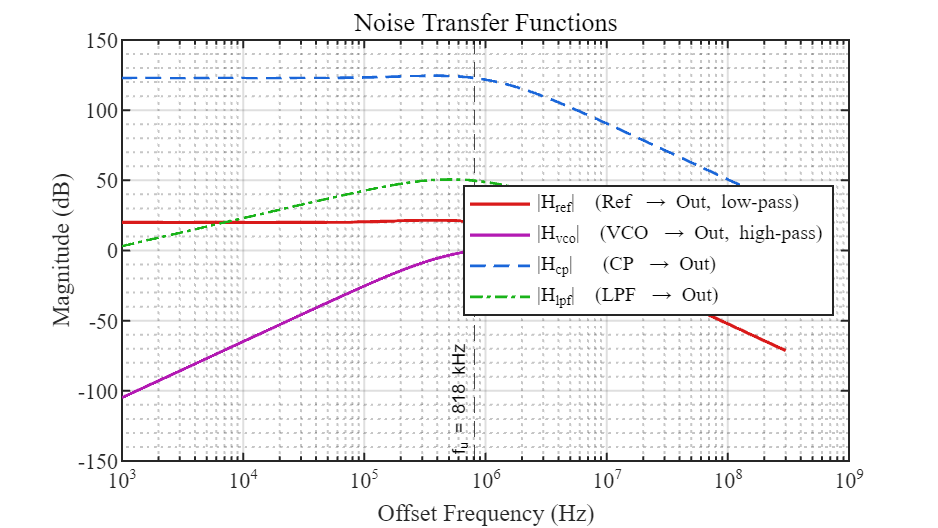


%% =========================================================================
%  FIGURES (3 total)
%% =========================================================================

%% --- Figure 1: Noise Transfer Functions -----------------------------------

figure('Position', [100 100 800 450]);

semilogx(f, 20*log10(abs(H)),     '-',  'Color', [0.85 0.1 0.1], 'LineWidth', 1.6);
hold on;
semilogx(f, 20*log10(abs(E)),     '-',  'Color', [0.7 0.1 0.7],  'LineWidth', 1.6);
semilogx(f, 20*log10(abs(P)),     '--', 'Color', [0.1 0.4 0.85], 'LineWidth', 1.4);
semilogx(f, 20*log10(abs(Lnode)), '-.', 'Color', [0.1 0.7 0.1],  'LineWidth', 1.4);

xline(fu, '--k', sprintf('f_u = %.0f kHz', fu/1e3), ...
      'LabelHorizontalAlignment', 'left', ...
      'LabelVerticalAlignment', 'bottom', 'FontSize', 9);

grid on; grid minor;
set(gca, 'FontSize', 11);
xlabel('Offset Frequency (Hz)', 'FontSize', 12);
ylabel('Magnitude (dB)', 'FontSize', 12);
title('Noise Transfer Functions', 'FontSize', 13);
legend({'|H_{ref}|  (Ref \rightarrow Out, low-pass)', ...
        '|H_{vco}|  (VCO \rightarrow Out, high-pass)', ...
        '|H_{cp}|   (CP \rightarrow Out)', ...
        '|H_{lpf}|  (LPF \rightarrow Out)'}, ...
       'FontSize', 10, 'Location', 'east');

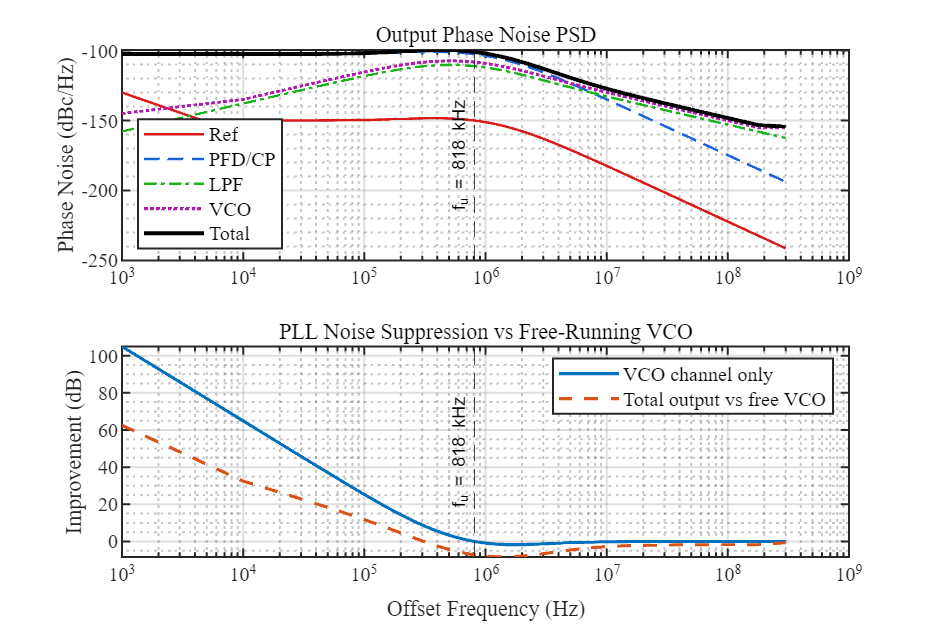


%% --- Figure 2: Output PN PSD + Improvement --------------------------------

figure('Position', [100 100 900 600]);

% (a) Total output phase noise with all contributions
subplot(2,1,1);

semilogx(f, PN_out_ref, '-',  'Color', [0.85 0.1 0.1], 'LineWidth', 1.3);
hold on;
semilogx(f, PN_out_pc,  '--', 'Color', [0.1 0.4 0.85], 'LineWidth', 1.3);
semilogx(f, PN_out_lpf, '-.', 'Color', [0.1 0.7 0.1],  'LineWidth', 1.3);
semilogx(f, PN_out_vco, ':',  'Color', [0.7 0.1 0.7],  'LineWidth', 1.6);
semilogx(f, PN_out,      'k-', 'LineWidth', 2.0);

xline(fu, '--k', sprintf('f_u = %.0f kHz', fu/1e3), ...
      'HandleVisibility', 'off', ...
      'LabelHorizontalAlignment', 'left', ...
      'LabelVerticalAlignment', 'middle', 'FontSize', 9);

grid on; grid minor;
set(gca, 'FontSize', 10);
ylabel('Phase Noise (dBc/Hz)');
title('Output Phase Noise PSD');
legend({'Ref', 'PFD/CP', 'LPF', 'VCO', 'Total'}, ...
       'FontSize', 10, 'Location', 'southwest');

% (b) Improvement relative to free-running VCO
improve_vco   = PN_vco - PN_out_vco;
improve_total = PN_vco - PN_out;

subplot(2,1,2);

semilogx(f, improve_vco,   '-',  'LineWidth', 1.6);
hold on;
semilogx(f, improve_total, '--', 'LineWidth', 1.6);

xline(fu, '--k', sprintf('f_u = %.0f kHz', fu/1e3), ...
      'HandleVisibility', 'off', ...
      'LabelHorizontalAlignment', 'left', ...
      'LabelVerticalAlignment', 'middle', 'FontSize', 9);

grid on; grid minor;
set(gca, 'FontSize', 10);
xlabel('Offset Frequency (Hz)');
ylabel('Improvement (dB)');
title('PLL Noise Suppression vs Free-Running VCO');
legend({'VCO channel only', 'Total output vs free VCO'}, ...
       'FontSize', 10, 'Location', 'northeast');

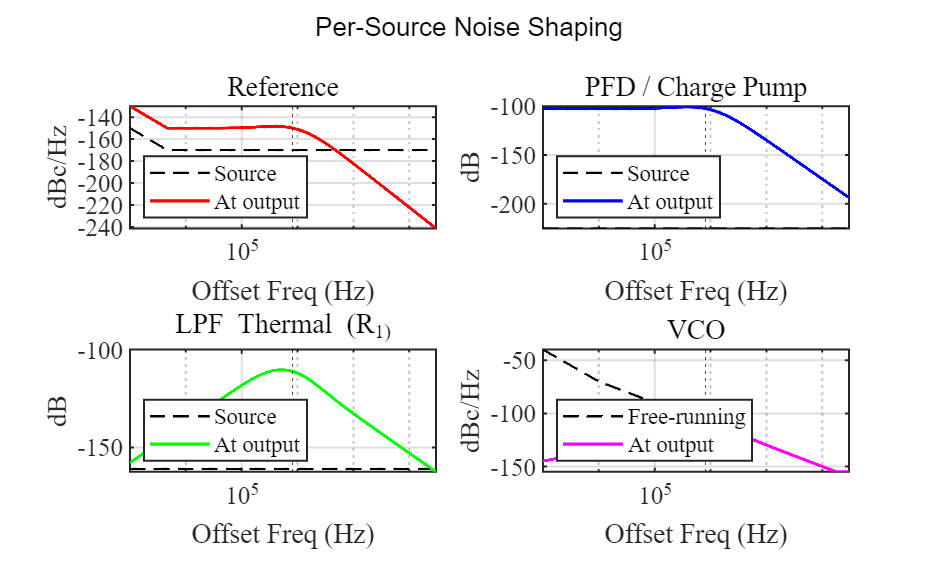


%% --- Figure 3: Per-Source Noise Shaping ------------------------------------

figure('Position', [100 100 1000 600]);

% Reference
subplot(2,2,1);
semilogx(f, PN_ref,     'k--', 'LineWidth', 1.2); hold on;
semilogx(f, PN_out_ref, 'r-',  'LineWidth', 1.6);
xline(fu, ':k', '', 'HandleVisibility', 'off');
grid on;
xlabel('Offset Freq (Hz)'); ylabel('dBc/Hz');
title('Reference');
legend('Source', 'At output', 'Location', 'southwest');

% PFD/CP
subplot(2,2,2);
semilogx(f, PN_pc,     'k--', 'LineWidth', 1.2); hold on;
semilogx(f, PN_out_pc, 'b-',  'LineWidth', 1.6);
xline(fu, ':k', '', 'HandleVisibility', 'off');
grid on;
xlabel('Offset Freq (Hz)'); ylabel('dB');
title('PFD / Charge Pump');
legend('Source', 'At output', 'Location', 'southwest');

% LPF Resistor
subplot(2,2,3);
semilogx(f, PN_lpf,     'k--', 'LineWidth', 1.2); hold on;
semilogx(f, PN_out_lpf, 'g-',  'LineWidth', 1.6);
xline(fu, ':k', '', 'HandleVisibility', 'off');
grid on;
xlabel('Offset Freq (Hz)'); ylabel('dB');
title('LPF Thermal (R_1)');
legend('Source', 'At output', 'Location', 'southwest');

% VCO
subplot(2,2,4);
semilogx(f, PN_vco,     'k--', 'LineWidth', 1.2); hold on;
semilogx(f, PN_out_vco, 'm-',  'LineWidth', 1.6);
xline(fu, ':k', '', 'HandleVisibility', 'off');
grid on;
xlabel('Offset Freq (Hz)'); ylabel('dBc/Hz');
title('VCO');
legend('Free-running', 'At output', 'Location', 'southwest');

sgtitle('Per-Source Noise Shaping', 'FontSize', 13);

%% --- Figure 4: IFFT Time-Domain Noise Synthesis ---------------------------
%  Reconstructs a phase noise time series from PN_out(f) via IFFT.
%  The synthesised signal preserves the exact spectral shape.
%
%  Subplots:
%    (a) Phase noise trajectory phi_noise(t)
%    (b) Ideal carrier
%    (c) Noisy carrier (jitter too small to see at this scale — expected)

% --- Synthesis parameters ---
rng(42);                                    % reproducible
f_max_synth = fout / 2;                     % carrier Nyquist (50 MHz)
df_synth    = 1e3;                          % 1 kHz resolution
f_uni       = (df_synth : df_synth : f_max_synth)';
Nf          = length(f_uni);
Nfft        = 2 * (Nf + 1);                % two-sided FFT length
Fs_synth    = Nfft * df_synth;              % ~100 MHz sampling rate

% --- Interpolate total output PN onto uniform grid ---
PN_uni = interp1(log10(f), PN_out, log10(f_uni), 'linear', 'extrap');
S_uni  = 10.^(PN_uni / 10);                % linear PSD, rad^2/Hz

% --- Build conjugate-symmetric spectrum ---
A_bin    = sqrt(S_uni * df_synth);          % amplitude per frequency bin
phi_rand = 2*pi * rand(Nf, 1);

X = zeros(Nfft, 1);
X(2:Nf+1)       = Nfft * A_bin .* exp(1i * phi_rand);   % positive freq
X(Nfft:-1:Nf+3) = conj(X(2:Nf+1));                     % negative freq

% --- IFFT → time-domain phase noise ---
phi_noise = real(ifft(X));
t_synth   = (0 : Nfft-1)' / Fs_synth;

% --- Verification: compare RMS ---
sigma_synth = std(phi_noise);
fprintf('\n=== IFFT Synthesis ===\n');


=== IFFT Synthesis ===


fprintf('Nfft = %d,  Fs = %.2f MHz,  df = %.0f Hz\n', ...
        Nfft, Fs_synth/1e6, df_synth);

Nfft = 100002,  Fs = 100.00 MHz,  df = 1000 Hz


fprintf('sigma_phi (synthesised) = %.4f rad  (analytical: %.4f rad)\n', ...
        sigma_synth, sigma_phi);

sigma_phi (synthesised) = 0.0166 rad  (analytical: 0.0166 rad)


fprintf('Ratio = %.2f  (ideal: 1.0)\n', sigma_synth / sigma_phi);

Ratio = 1.00  (ideal: 1.0)


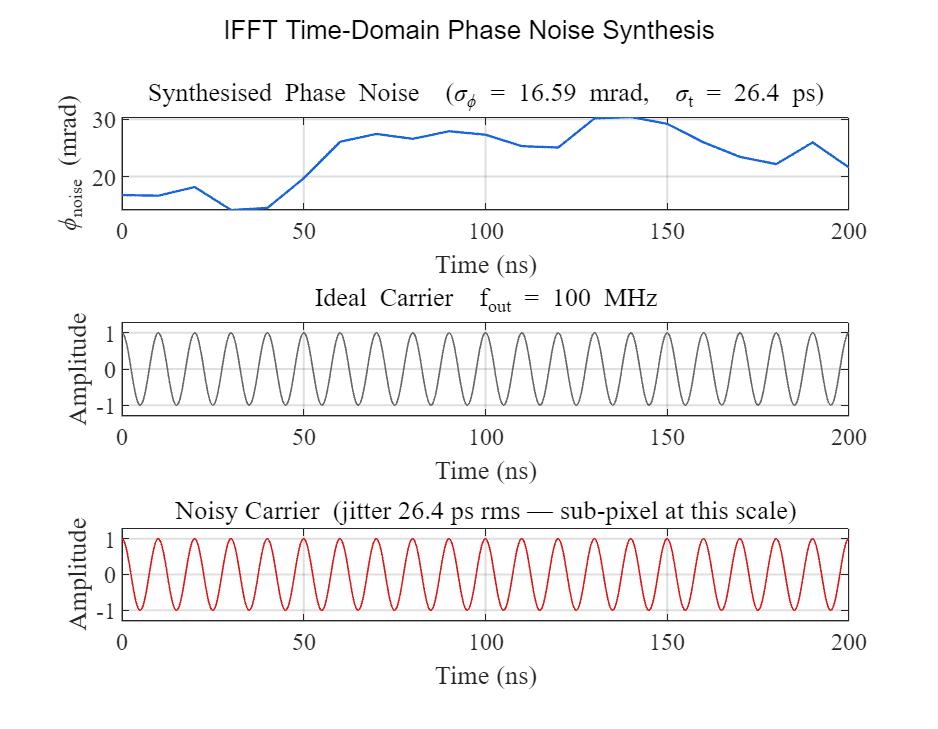


% --- PSD verification via pwelch ---
nwin = min(Nfft, round(Nfft/4));           % window length
[Pxx, f_pxx] = pwelch(phi_noise, hann(nwin), [], [], Fs_synth, 'onesided');
PN_verify = 10*log10(Pxx);                 % dBc/Hz (onesided already SSB)

% --- Display window: 20 carrier periods ---
T_display  = 20 / fout;                    % 200 ns
Fs_display = 50 * fout;                    % 5 GHz for smooth waveform
t_fine     = (0 : 1/Fs_display : T_display)';

phi_fine = interp1(t_synth, phi_noise, t_fine, 'linear', 'extrap');
v_ideal  = cos(2*pi*fout * t_fine);
v_noisy  = cos(2*pi*fout * t_fine + phi_fine);

% --- Plot (3 subplots) ---
figure('Position', [100 100 900 700]);

subplot(3,1,1);
plot(t_fine*1e9, phi_fine*1e3, 'LineWidth', 1.2, 'Color', [0.1 0.4 0.85]);
grid on;
xlabel('Time (ns)'); ylabel('\phi_{noise} (mrad)');
title(sprintf('Synthesised Phase Noise  (\\sigma_\\phi = %.2f mrad,  \\sigma_t = %.1f ps)', ...
      sigma_synth*1e3, jitter_ps), 'FontSize', 11);

subplot(3,1,2);
plot(t_fine*1e9, v_ideal, 'LineWidth', 0.8, 'Color', [0.4 0.4 0.4]);
grid on; ylim([-1.3 1.3]);
xlabel('Time (ns)'); ylabel('Amplitude');
title(sprintf('Ideal Carrier  f_{out} = %.0f MHz', fout/1e6), 'FontSize', 11);

subplot(3,1,3);
plot(t_fine*1e9, v_noisy, 'LineWidth', 0.8, 'Color', [0.85 0.1 0.1]);
grid on; ylim([-1.3 1.3]);
xlabel('Time (ns)'); ylabel('Amplitude');
title(sprintf('Noisy Carrier  (jitter %.1f ps rms — sub-pixel at this scale)', jitter_ps), ...
      'FontSize', 11);

sgtitle('IFFT Time-Domain Phase Noise Synthesis', 'FontSize', 13);

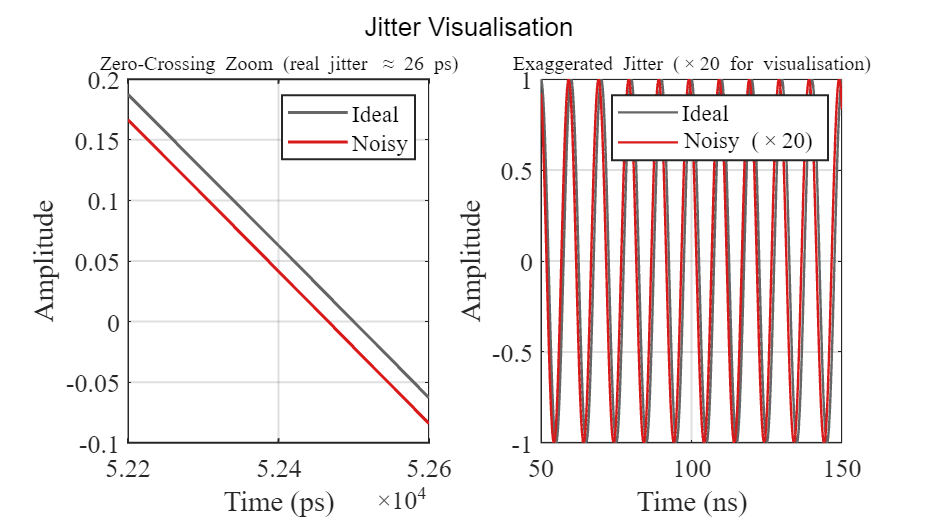

%% --- Figure 4b: Zoomed Zero-Crossing + Exaggerated Jitter ----------------

figure('Position', [100 100 900 500]);

% --- (a) Zoomed zero-crossing: real jitter ---
% Find a falling zero-crossing of ideal carrier near t = 50 ns
t_zc_target = 50e-9;
idx_near = find(t_fine > t_zc_target, 1);
% Search for falling zero-crossing (positive → negative)
for kk = idx_near : length(t_fine)-1
    if v_ideal(kk) > 0 && v_ideal(kk+1) <= 0
        idx_zc = kk; break;
    end
end

% Window: ±200 ps around crossing
dt_zoom = 200e-12;
idx_zoom = (t_fine >= t_fine(idx_zc) - dt_zoom) & ...
           (t_fine <= t_fine(idx_zc) + dt_zoom);

subplot(1,2,1);
plot(t_fine(idx_zoom)*1e12, v_ideal(idx_zoom), '-', ...
     'Color', [0.4 0.4 0.4], 'LineWidth', 1.5);
hold on;
plot(t_fine(idx_zoom)*1e12, v_noisy(idx_zoom), '-', ...
     'Color', [0.85 0.1 0.1], 'LineWidth', 1.5);
grid on;
xlabel('Time (ps)'); ylabel('Amplitude');
title(sprintf('Zero-Crossing Zoom (real jitter \\approx %.0f ps)', jitter_ps), ...
      'FontSize', 10);
legend('Ideal', 'Noisy', 'Location', 'northeast');

% --- (b) Exaggerated jitter (×100) ---
scale_factor = 20;
v_exag = cos(2*pi*fout * t_fine + scale_factor * phi_fine);

% Show 10 periods centred around t = 50 ns
T_show = 10 / fout;
idx_show = (t_fine >= 50e-9) & (t_fine <= 50e-9 + T_show);

subplot(1,2,2);
plot(t_fine(idx_show)*1e9, v_ideal(idx_show), '-', ...
     'Color', [0.4 0.4 0.4], 'LineWidth', 1.2);
hold on;
plot(t_fine(idx_show)*1e9, v_exag(idx_show), '-', ...
     'Color', [0.85 0.1 0.1], 'LineWidth', 1.2);
grid on;
xlabel('Time (ns)'); ylabel('Amplitude');
title(sprintf('Exaggerated Jitter (\\times%d for visualisation)', scale_factor), ...
      'FontSize', 10);
legend('Ideal', sprintf('Noisy (\\times%d)', scale_factor), 'Location', 'northeast');

sgtitle('Jitter Visualisation', 'FontSize', 13);

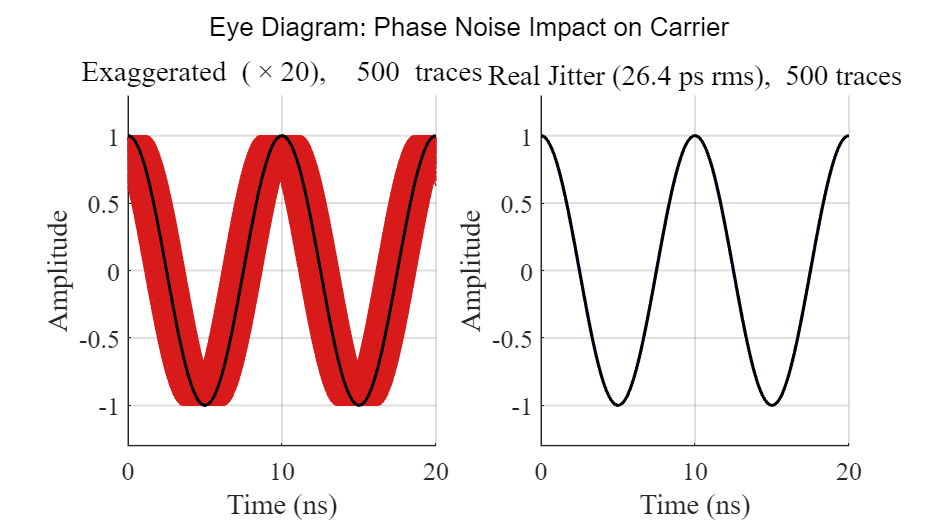



%% --- Figure 4c: Eye Diagram -----------------------------------------------
%  Generates traces efficiently: one short high-res segment per crossing,
%  interpolating phi_noise at each point.

T_carrier   = 1 / fout;
npts_trace  = 200;                                  % points per 2-period trace
t_trace     = linspace(0, 2*T_carrier, npts_trace); % local time axis

% Use full IFFT time series (t_synth, phi_noise) — spans ~1 ms, plenty of crossings
% Identify rising zero-crossings of ideal carrier at Fs_synth rate
phase_ideal_synth = mod(2*pi*fout*t_synth, 2*pi);
idx_cross = find(phase_ideal_synth(2:end) < phase_ideal_synth(1:end-1)) + 1;

max_traces = 500;
if length(idx_cross) > max_traces
    idx_cross = idx_cross(1:max_traces);
end
n_traces = length(idx_cross);

figure('Position', [100 100 900 500]);

% --- Left: Exaggerated (×100) ---
subplot(1,2,1);
hold on;
for kk = 1:n_traces
    t_abs = t_synth(idx_cross(kk)) + t_trace';
    phi_seg = interp1(t_synth, phi_noise, t_abs, 'linear', 'extrap');
    v_seg = cos(2*pi*fout*t_trace' + scale_factor * phi_seg);
    plot(t_trace*1e9, v_seg, '-', 'Color', [0.85 0.1 0.1 0.08], 'LineWidth', 0.5);
end
plot(t_trace*1e9, cos(2*pi*fout*t_trace), 'k-', 'LineWidth', 1.5);
grid on; ylim([-1.3 1.3]);
xlabel('Time (ns)'); ylabel('Amplitude');
title(sprintf('Exaggerated (\\times%d),  %d traces', scale_factor, n_traces), 'FontSize', 10);

% --- Right: Real jitter ---
subplot(1,2,2);
hold on;
for kk = 1:n_traces
    t_abs = t_synth(idx_cross(kk)) + t_trace';
    phi_seg = interp1(t_synth, phi_noise, t_abs, 'linear', 'extrap');
    v_seg = cos(2*pi*fout*t_trace' + phi_seg);
    plot(t_trace*1e9, v_seg, '-', 'Color', [0.1 0.4 0.85 0.08], 'LineWidth', 0.5);
end
plot(t_trace*1e9, cos(2*pi*fout*t_trace), 'k-', 'LineWidth', 1.5);
grid on; ylim([-1.3 1.3]);
xlabel('Time (ns)'); ylabel('Amplitude');
title(sprintf('Real Jitter (%.1f ps rms),  %d traces', jitter_ps, n_traces), 'FontSize', 10);

sgtitle('Eye Diagram: Phase Noise Impact on Carrier', 'FontSize', 13);

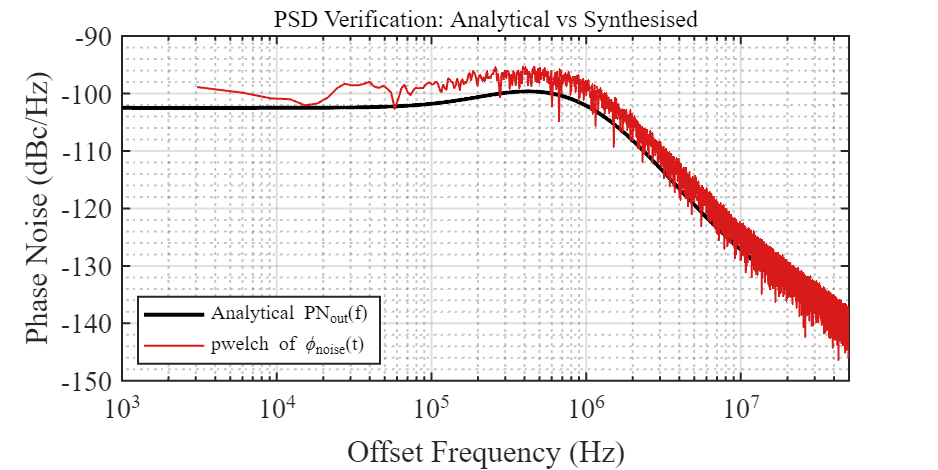


% --- Verification figure: PSD overlay ---
figure('Position', [100 100 800 400]);
semilogx(f, PN_out, 'k-', 'LineWidth', 2.0); hold on;
semilogx(f_pxx, PN_verify, '-', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.0);
grid on; grid minor;
xlabel('Offset Frequency (Hz)'); ylabel('Phase Noise (dBc/Hz)');
title('PSD Verification: Analytical vs Synthesised', 'FontSize', 12);
legend({'Analytical PN_{out}(f)', 'pwelch of \phi_{noise}(t)'}, ...
       'FontSize', 10, 'Location', 'southwest');
xlim([1e3 f_max_synth]);

%% === Console Summary =====================================================
fprintf('\n============================================\n');

fprintf('  NOISE MODEL SUMMARY (v2 — physics-based)\n');

  NOISE MODEL SUMMARY (v2 — physics-based)


fprintf('============================================\n');

fprintf('Source          | Model              | Key value\n');

Source          | Model              | Key value


fprintf('----------------|--------------------|-----------------------\n');

----------------|--------------------|-----------------------


fprintf('Reference       | -30 dB/dec, floor  | %.0f dBc/Hz @ 1 kHz\n', PN_ref_anchor);

Reference       | -30 dB/dec, floor  | -150 dBc/Hz @ 1 kHz


fprintf('VCO             | -20 dB/dec, floor  | %.0f dBc/Hz @ 100 kHz\n', PN_vco_anchor);

VCO             | -20 dB/dec, floor  | -90 dBc/Hz @ 100 kHz


fprintf('CP (shot noise) | flat, 4qIcp        | %.1f dB(A^2/Hz)\n', 10*log10(S_icp));

CP (shot noise) | flat, 4qIcp        | -225.4 dB(A^2/Hz)


fprintf('LPF (thermal)   | flat, 4kTR1        | %.1f dB(V^2/Hz)\n', 10*log10(S_v_R1));

LPF (thermal)   | flat, 4kTR1        | -160.9 dB(V^2/Hz)


fprintf('----------------|--------------------|-----------------------\n');

----------------|--------------------|-----------------------


fprintf('Jitter          | [%.0fk-%.1fM Hz]   | %.3f ps rms\n', ...
        f_jitter_min/1e3, f_jitter_max/1e6, jitter_ps);

Jitter          | [1k-50.0M Hz]   | 26.405 ps rms


fprintf('============================================\n');